# SIR Model: Flu Epidemic

## Task 1

The system of ODEs governing the flu epidemic is

dSdt=−rSI

dIdt=rSI−aI

dRdt=aI 

where 

r=0.00218, a=0.5, and t

 is measured in days. There are initially 999 susceptible, 1 infected, and none recovered. The epidemic lasts 14 days.

Task

Solve the system of ODEs for the first 14 days of the flu epidemic by:

- defining the time interval `tRange`, 

- defining the initial condition vector `Y0`, 

- writing a local function `SIRmodel` to represent the system of ODEs, 

- calling `ode45` to solve the system, assigning the outputs to `tSol` and `YSol`.

*Remember to write the local function *`SIRmodel `*at the bottom of this script*.

tRange=[0 14]

tRange =      0    14


Y0=[999; 1; 0]

Y0 =    999
     1
     0


[tSol,YSol]=ode45(@SIRmodel,tRange,Y0)

tSol =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0009
    0.0014
    0.0019
    0.0024
    0.0049


YSol =   999.0000    1.0000         0
  998.9998    1.0002    0.0001
  998.9996    1.0003    0.0001
  998.9993    1.0005    0.0002
  998.9991    1.0007    0.0002
  998.9980    1.0015    0.0005
  998.9969    1.0024    0.0007
  998.9958    1.0032    0.0010
  998.9947    1.0041    0.0012
  998.9892    1.0083    0.0025


## Task 2

Extract the susceptible, infected, and recovered populations from the solution matrix `YSol`, and assign them to the variables `S`, `I`, and `R`, respectively.

Plot `S`, `I`, and `R` as functions of time together in the same figure. Add a descriptive legend to the figure.

S=YSol(:,1)

S =   999.0000
  998.9998
  998.9996
  998.9993
  998.9991
  998.9980
  998.9969
  998.9958
  998.9947
  998.9892


I=YSol(:,2)

I =     1.0000
    1.0002
    1.0003
    1.0005
    1.0007
    1.0015
    1.0024
    1.0032
    1.0041
    1.0083


R=YSol(:,3)

R =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


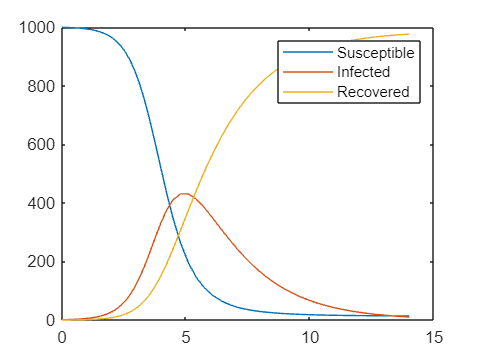

plot(tSol,S)
hold on
plot(tSol,I)
plot(tSol,R)
hold off
legend("Susceptible","Infected","Recovered")

## Task 3

Find the maximum value of the infected population at any given time during the two weeks. Assign it to the variable `maxI`. 

How far into the epidemic did the maximum occur? Assign the *time* when the maximum infected population occurred to the variable `peakFlu`.

Remember you can call the `max` function with two outputs to find both the maximum value and its index.

[xmax,idx] = max(x)

[maxI,idx]=max(I)

maxI = 430.5016

idx = 46

peakFlu=tSol(idx)

peakFlu = 4.7747

## Task 4

After two weeks, how many people had *not* gotten the flu? In other words, how many people remained in the susceptible population? Assign your result to the variable `noFlu`.

You may want to leave off the semicolon to display the result.

noFlu=S(end)

noFlu = 13.8939

## Further Practice

The epidemic began with a total population of 1000 people, and ideally  the total population in the solution is 1000 at each time step. 

Do the three populations add to 1000 at all times? You can plot the  difference between the sum of the populations and 1000 to see the error  at each time step.

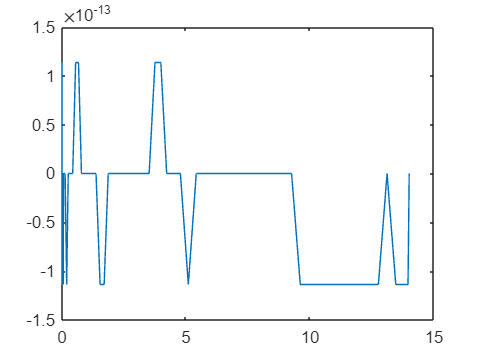

popError = sum(YSol,2) - 1000;
plot(tSol,popError)

You may have noticed that there are "fractional" people in the results,  too. Round the results to the nearest whole number, and then see if the  three populations add to 1000.

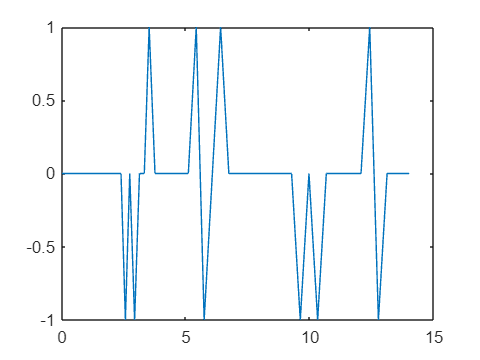

popErrorRnd = sum(round(YSol),2) - 1000;
plot(tSol,popErrorRnd)

## Task 1 (continued)

Define the ODE function `SIRmodel`.

% TODO - Write the function declaration. Name the function SIRmodel

function dYdt=SIRmodel(t,Y)
% TODO - Extract S, I, and R from input vector Y
S=Y(1);
I=Y(2);
R=Y(3);
% TODO - Define the constants r and a
r=0.00218;
a=0.5;
% TODO - Define dSdt, dIdt, dRdt from the ODEs
dSdt=-r.*S.*I;
dIdt=r.*S.*I-a.*I;
dRdt=a.*I;
% TODO - Create output column vector dYdt
dYdt=[dSdt;dIdt;dRdt];
end